## Parse the data from the specs

clear
structure = SpecParser("global_specs.txt")

structure = struct with fields:
               task_type: 'wav'
            wav_filename: 'animal_call.wav'
                  wav_fs: 20000
             signal_type: 'tone'
                      fs: 10000
       signal_duration_s: 3
           periodicity_s: 0.5000
             frequencies: [1000 2000 4000 8000]
     spectral_resolution: 0.5000
             window_type: 'hann'
            stft_overlap: 50
               filtering: 'iir'
            filter_order: 2
    approximation_method: 'butterworth'
             filter_type: 'lp'
       cut_off_frequency: 1000
              x_lim_time: 2
         y_lim_amplitude: 1
             x_axis_type: 'log'
             y_axis_type: 'log'
         x_lim_frequency: 'nyquist'
                y_lim_au: 40


## Signal selection, .wav read, resample

task_type = structure.task_type % Determine whether to generate or read .wav

task_type = 'wav'

if strcmp(task_type, 'wav') % Check if the task is related to audio processing

    % Get the directory and file name for the audio file
    dir_name = pwd; % Current working directory
    f_name = structure.wav_filename; % Audio file name from structure

    % Read the audio file
    [y, fs_o] = audioread(fullfile(dir_name, f_name)); % Load audio and original sampling frequency
    y = y(:, 1); % Convert stereo to mono by selecting one channel

    % Target sampling frequency
    fs = structure.wav_fs; % Desired sampling frequency from structure

    % Resample the audio if the sampling frequency is different
    if fs_o ~= fs
        signal = resample(y, fs, fs_o); % Resample from original to target frequency
    else
        signal = y; % No resampling needed
    end

    % Generate a time vector corresponding to the audio signal
    t = (0:length(signal) - 1) / fs; % Time vector (seconds)
    t = t(:); % Ensure column vector format

    % Save the processed data (time and signal) to a file
    % 'save_data' function should save data with labels for clarity
    save_data({t, signal}, {'Time', 'Amplitude'}, 'audio_signal');
end


## Generate signal

if strcmp(task_type, 'generate') % Check if the task is to generate a signal

    % Extract parameters from the structure
    type = structure.signal_type; % Signal type ('rect', 'tone', 'tone-complex', 'noise')
    fs = structure.fs; % Sampling frequency
    duration = structure.signal_duration_s; % Duration of the signal in seconds
    frequencies = structure.frequencies; % Frequencies to include in the signal
    t = 0:1/fs:duration-1/fs; % Time vector for the signal
    signal = zeros(1, length(t)); % Initialize the signal array with zeros

    % Generate a rectangular wave if specified
    if strcmp(type, 'rect')
        periodicity = structure.periodicity_s; % Periodicity of the rectangular wave
        % Use the sine function and the sign function to generate a rectangular waveform
        signal = sign(sin(2 * pi / periodicity * t)); % Construct the rectangular wave
    end

    % Generate a tone (sum of sinusoidal components) if specified
    if strcmp(type, 'tone')
        for i = 1:length(frequencies) % Iterate through the list of frequencies
            signal = signal + cos(2 * pi * frequencies(i) * t); % Add sinusoidal component
        end
    end

    % Generate a tone-complex (sum of sinusoidal components with random phases) if specified
    if strcmp(type, 'tone-complex')
        for i = 1:length(frequencies) % Iterate through the list of frequencies
            phase = rand() * 2 * pi; % Random phase between 0 and 2π
            signal = signal + cos(2 * pi * frequencies(i) * t + phase); % Add sinusoidal component with random phase
        end
    end

    % Generate random noise if specified
    if strcmp(type, 'noise')
        signal = rand(1, fs * duration) - 0.5; % Generate random values in the range [-0.5, 0.5]
    end

    % Save the generated signal to a file
    % 'save_data' should save time and amplitude vectors with appropriate labels
    save_data({t, signal}, {'Time', 'Amplitude'}, 'generated_signal');

end

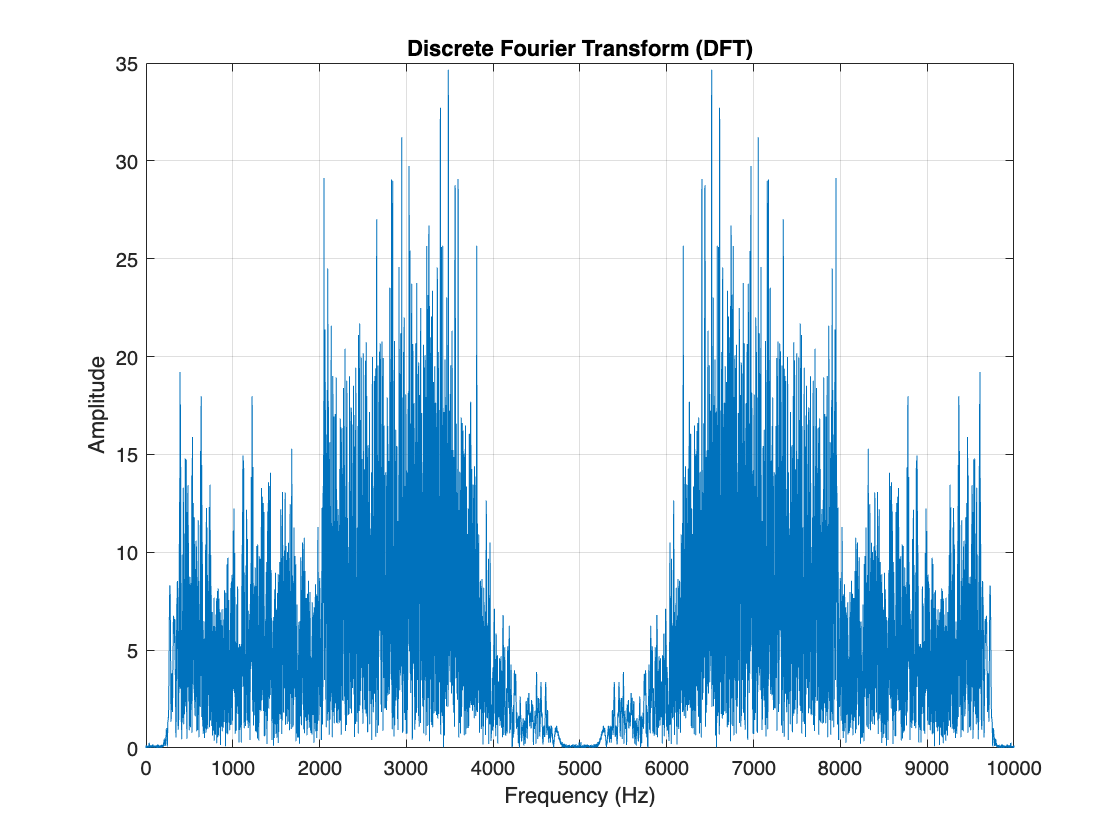

% Inputs and structure parameters
signal = y; % Input signal
fs = structure.fs; % Sampling frequency
spectral_resolution = structure.spectral_resolution; % Frequency resolution
window_type = structure.window_type; % Window type ('hann', 'hamming', 'rect')
overlap = structure.stft_overlap; % Overlap percentage for STFT

% Validate window type
if ~ismember(window_type, ["hann", "hamming", "rect"])
    error("Invalid window type. Use 'hann', 'hamming', or 'rect'.");
end

% DFT length for desired spectral resolution
N = round(fs / spectral_resolution);
L = length(signal);

% Window signal for DFT based on the signal length and DFT length
if N < L
    % Use the appropriate window type
    switch window_type
        case "hann"
            winDFT = hann(N);
        case "hamming"
            winDFT = hamming(N);
        case "rect"
            winDFT = ones(N, 1);
    end
    y_win = winDFT .* signal(1:N); % Window only the first N samples
else
    switch window_type
        case "hann"
            winDFT = hann(L);
        case "hamming"
            winDFT = hamming(L);
        case "rect"
            winDFT = ones(L, 1);
    end
    y_win = winDFT .* signal; % Window the entire signal
end

% Compute the DFT
y_dft = fft(y_win, N);

% Plot the DFT
figure;
freq_dft = (0:N-1) * (fs / N); % Frequency axis for DFT
plot(freq_dft, abs(y_dft));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Discrete Fourier Transform (DFT)');
grid on;

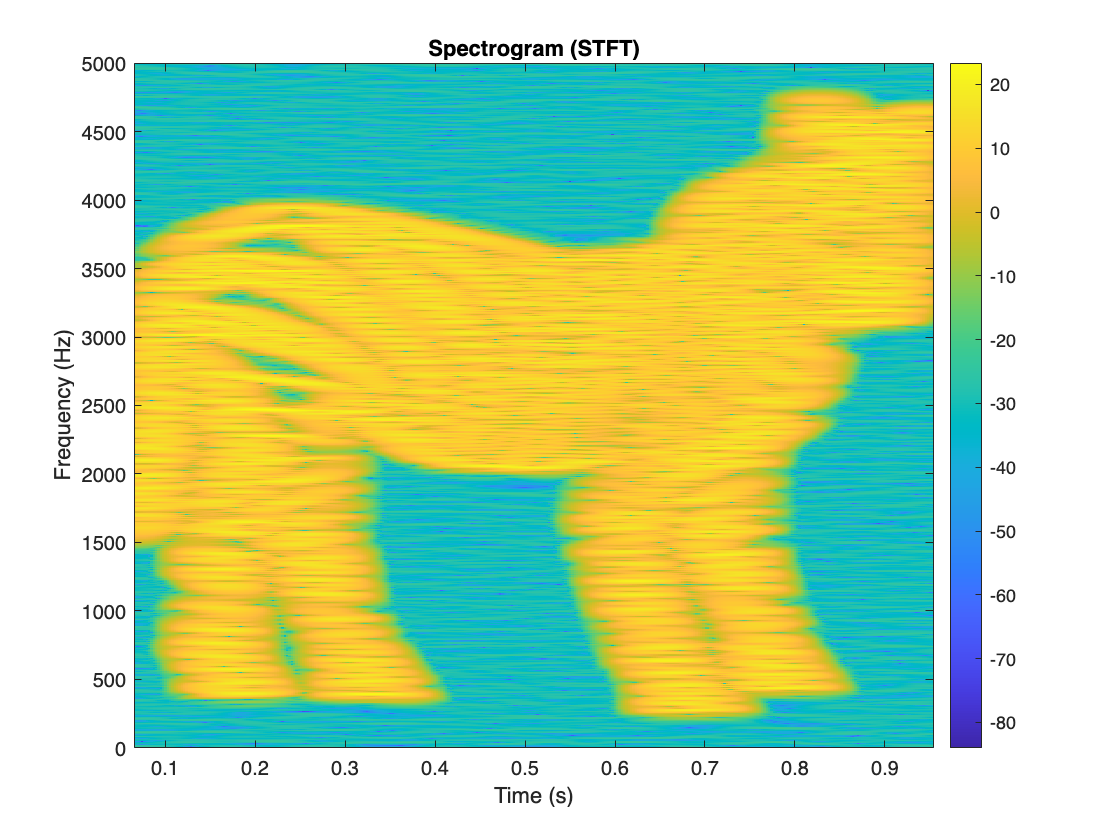


% Calculate window length for STFT
winLength = round(N / 15); % Arbitrary choice for time-frequency resolution balance
switch window_type
    case "hann"
        winSTFT = hann(winLength);
    case "hamming"
        winSTFT = hamming(winLength);
    case "rect"
        winSTFT = ones(winLength, 1);
    otherwise
        error("Invalid window type. Use 'hann', 'hamming', or 'rect'.");
end

% Compute STFT
overlap_samples = round(winLength * overlap / 51);
[y_stft, f_stft, t_stft] = stft(signal, fs, ...
    'FrequencyRange', 'onesided', ...
    'Window', winSTFT, ...
    'OverlapLength', overlap_samples, ...
    'FFTLength', 2^(nextpow2(winLength))); % Ensure FFT length is a power of 2

% Plot the STFT (Spectrogram)
figure;
imagesc(t_stft, f_stft, 20 * log10(abs(y_stft))); % Convert to dB scale
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram (STFT)');
colorbar;

% Optional: Save the spectrogram plot
saveas(gcf, 'STFT.pdf');

## DFT

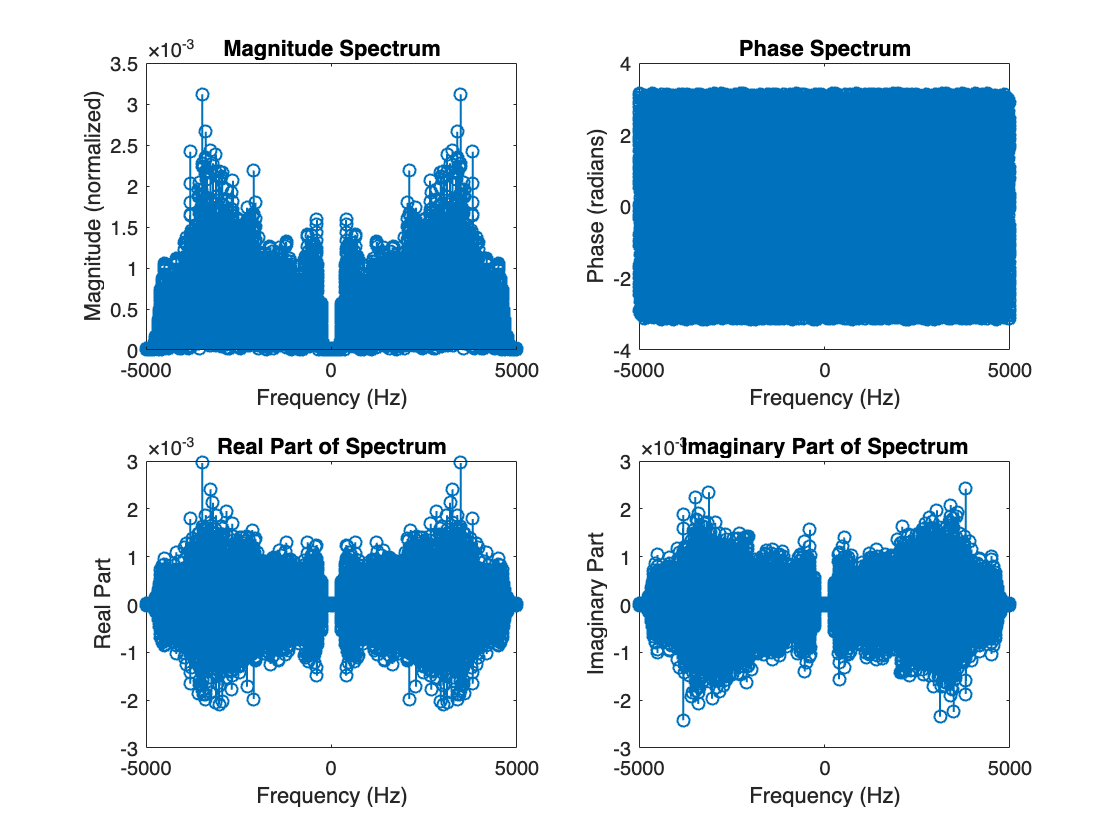

% Generate the normalized spectrum of a signal.
% Inputs:
%   signal - The input signal in the time domain.
%   fs - Sampling frequency of the signal.
%   spectral_resolution - Desired spectral resolution (e.g., [0.2, 0.5, 1]).
%
% The function calculates the normalized spectrum using the Discrete Fourier Transform (DFT).
% The spectral resolution is achieved by resampling the transformed signal to match the required resolution.
% Note: The `resample` function requires integers for its inputs `p` and `q`,
% which means the inverse of the spectral resolution (1/spectral_resolution) must be an integer.

spectral_resolution = structure.spectral_resolution; % Required spectral resolution

% Call the spectrum generation function to calculate the spectrum (Y) and frequency vector (f)
[Y, f] = make_spectrum(signal, fs, spectral_resolution); % Function to compute the DFT and normalize

% Save spectrum and frequency vector
%save_data({f, abs(Y), real(Y), imag(Y)},{'Frequency', 'Magnitude', 'Real', 'Imaginary'},'dft_signal');

## **STFT**

% Generate and save a spectrogram (STFT) based on the given signal and parameters.
% Inputs:
%   overlap - Overlap percentage for the STFT.
%   window_type - Type of window to use ('hann', 'hamming', 'rect').
%   spectral_resolution - Desired spectral resolution.
%   fs - Sampling frequency of the signal.

overlap = structure.stft_overlap; % Overlap for STFT in percent
window_type = structure.window_type; % Window type ('hann', 'hamming', 'rect')

figure();

% Determine window length based on spectral resolution
if strcmp(window_type, 'rect')
    N = 2 * fs / spectral_resolution; % Shorter window for rectangular window
else
    N = 4 * fs / spectral_resolution; % Default window length for 'hann' and 'hamming'
end

% Generate the window based on the specified type
switch window_type
    case 'hann'
        w = hann(round(N)); % Generate a Hann window
    case 'hamming'
        w = hamming(round(N)); % Generate a Hamming window
    case 'rect'
        w = rectwin(round(N)); % Generate a rectangular window
    otherwise
        error('Invalid window type. Valid options: hann, hamming, rect.');
end

% Calculate overlap in samples
overlap_n = round(overlap / 100 * N);

% Generate the spectrogram
spectrogram(signal, w, overlap_n, [], fs, 'yaxis');

Error using signal.internal.spectral.welchparse>segmentInfo (line 240)
The length of the segments cannot be greater than the length of the input signal.

Error in signal.internal.spectral.welchparse (line 145)
[L,noverlap,win] = segme


% Add title and save the spectrogram plot
title("Spectrogram (STFT)");
%save_plot('STFT');


## Filter design

% Ensure 'fs' (sampling frequency) is defined
if isempty(fs)
    error('Sampling frequency fs is not defined.');
end

% Extract filter specifications from the structure
filtering = structure.filtering; % Type of filter ('iir' or 'fir')
filter_type = structure.filter_type; % Filter type ('lp', 'hp', 'bp', 'bs')
approximation_method = structure.approximation_method; % Approximation method
filter_order = structure.filter_order; % Filter order

% Validate cutoff frequency based on filter type
if strcmpi(filter_type, 'lp') || strcmpi(filter_type, 'hp')
    % Lowpass or highpass filter requires a scalar cutoff frequency
    if numel(structure.cut_off_frequency) ~= 1
        error('Lowpass and highpass filters require a single cutoff frequency.');
    end
    cutoff_freqs_norm = structure.cut_off_frequency / (fs / 2); % Normalize
    if cutoff_freqs_norm <= 0 || cutoff_freqs_norm >= 1
        error('Cutoff frequency for lowpass/highpass must be in the range (0, fs/2).');
    end
elseif strcmpi(filter_type, 'bp') || strcmpi(filter_type, 'bs')
    % Bandpass or bandstop filters require two cutoff frequencies
    if numel(structure.cut_off_frequency) ~= 2
        error('Bandpass and bandstop filters require two cutoff frequencies.');
    end
    cutoff_freqs_norm = structure.cut_off_frequency / (fs / 2); % Normalize
    if any(cutoff_freqs_norm <= 0) || any(cutoff_freqs_norm >= 1) || ...
            cutoff_freqs_norm(1) >= cutoff_freqs_norm(2)
        error('Cutoff frequencies for bandpass/bandstop must be in the range (0, fs/2) and increasing.');
    end
else
    error('Invalid filter type specified.');
end

Cutoff frequency for lowpass/highpass must be in the range (0, fs/2).


% Design the filter based on the specified type
if strcmpi(filtering, 'iir')
    % Design an IIR filter
    [b_iir, a_iir] = designIIRfilter(filter_type, approximation_method, filter_order, cutoff_freqs_norm);
    b = b_iir;
    a = a_iir;

elseif strcmpi(filtering, 'fir')
    % Design an IIR filter first, then approximate it as an FIR filter
    [b_iir, a_iir] = designIIRfilter(filter_type, approximation_method, filter_order, cutoff_freqs_norm);
    [b_fir, a_fir] = iir_to_fir(b_iir, a_iir, filter_order);
    b = b_fir;
    a = a_fir;

else
    error('Invalid filtering type specified.');
end

% Apply the designed filter to the signal
filtered_data_signal = filter(b, a, signal);

% Generate time vector for the filtered signal
t_filtered = (0:length(filtered_data_signal) - 1) / fs;
t_filtered = t_filtered(:);

%% Display and Save Filter Coefficients

% Ensure 'a' and 'b' are column vectors
if isrow(a)
    a = a';
end
if isrow(b)
    b = b';
end

% Convert 'a' and 'b' to row vectors for display
a_row = a(:).';
b_row = b(:).';

% Convert coefficients to string representations
a_str = num2str(a_row);
b_str = num2str(b_row);

% Display the filter coefficients
disp('Filter Coefficients:');
disp(['b (Numerator): ', b_str]);
disp(['a (Denominator): ', a_str]);

% Save the filter coefficients to a text file
save_coefficients(a, b);

%% Save Filtered Signal (Optional)

% Save the filtered signal data (assuming 'save_data' function exists)
% save_data({t_filtered, filtered_data_signal}, {'Time', 'Filtered Amplitude'}, 'filtered_signal');

disp('Filtering completed successfully.');

## Plotting

Read parameters from spec sheet

% Time plots
x_lim = structure.x_lim_time;
y_lim = structure.y_lim_amplitude;

% Frequency plots
x_axis_type = structure.x_axis_type;
y_axis_type = structure.y_axis_type;
x_lim_freq = structure.x_lim_frequency; 
y_lim_au = structure.y_lim_au;

**1) Time signals: Original + Filtered**

Filtered_magnitude = abs(Filtered_Y);

Unrecognized function or variable 'Filtered_Y'.


% Plot the magnitude spectra of both signals on the same plot
figure;

% Plot the original signal spectrum using 'plot'
plot(freq, Original_magnitude, 'b', 'LineWidth', 1); % Original signal in blue
hold on;

% Plot the filtered signal spectrum using 'area' with transparency
% Create a filled area under the filtered signal's magnitude spectrum
h_area = area(freq, Filtered_magnitude);
set(h_area, 'FaceColor', 'r', 'EdgeColor', 'r', 'FaceAlpha', 0.4);

% Set plot properties
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Amplitude Spectrum');
legend('Original Signal', 'Filtered Signal');
grid on;
xlim([0 fs/2]); % Limit x-axis to positive frequencies up to Nyquist frequency

hold off;

**2) Magnitude/phase of Original Signal**

figure
sgtitle( 'Magnitude and Phase of signal' ,'FontSize', 14)
% Only positive frequencies
fposit=f(f>=0); % length(f)/2 +1 (DC offset)
Yposit=Y(f>=0);
magnitude=abs(Yposit);
phase=angle(Yposit);

% Magnitude diagram ------------------------
% Specifications

% Correct string comparison for 'nyquist'
if strcmpi(x_lim_freq, 'nyquist') % Case-insensitive comparison
    x_lim_freq = fs / 2; % If 'nyquist', then set x_lim_freq to fs/2
else
    x_lim_freq_num = str2double(x_lim_freq);
    if isnan(x_lim_freq_num)
        error('Invalid value for x_lim_freq. It must be a numeric value or ''nyquist''.');
    else
        x_lim_freq = x_lim_freq_num;
    end
end

subplot(2, 1, 1);
ax = gca;
if y_axis_type == 'lin' % Frequency as a.u.
    if x_axis_type == 'lin' 
        stem(fposit, magnitude,'linewidth',1);
        ax.XLim = [0 x_lim_freq];
        xlabel('Frequency(Hz)');
    else
        % not using semilogx because preferred to used stem.
        stem(log10(fposit), magnitude,'linewidth',1)
        ax.XLim = [0 log10(x_lim_freq)];
        xlabel('Frequency (log_{10}(Hz)))');
    end
    ylabel('Magnitude (a.u.)')
    ax.YLim = [0 y_lim_au];
else % Frequency as decibels.
    if x_axis_type == 'lin' 
        stem(fposit, 20*log10(magnitude),'linewidth',1);
        ax.XLim = [0 x_lim_freq];
        xlabel('Frequency(Hz)');
    else
        stem(log10(fposit), 20*log10(magnitude),'linewidth',1); % not using semilogx, preferred to used stem.
        ax.XLim = [0 log10(x_lim_freq)];
        xlabel('Frequency (20log_{10}(Hz)))');
    end
    ylabel('Magnitude (dB)')
    ax.YLim = [min([20*log10(y_lim_au);20*log10(magnitude);0]), max([20*log10(y_lim_au);0;20*log10(magnitude)]) ];
end
set(ax,'FontSize',10)
grid()
title('Magnitude')


% Phase diagram ------------------------
subplot(2, 1, 2);
ax=gca;
plot(fposit, unwrap(phase)*180/pi,'linewidth',1);
title('Phase unwrapped');
ax.XLim = [0 x_lim_freq];
set(ax,'Fontsize',10) 
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid()
set(gca,'Fontsize',10) % xtick could be added in specs and set here.
save_plot('magnitude_phase');

**3) Real/Imaginary parts of Original Signal**

figure()
sgtitle('Real and Imaginary parts of signal','FontSize', 14)
% Plot the real and imaginary parts of the original and filtered signals
subplot(2, 1, 1);
stem(f,real(Y),'.');
xlabel('Frequency (Hz)')
%ylim([-y_lim_au,y_lim_au])
ylabel('Amplitude / a.u.')
title("Real Part")
grid()
set(gca,'Fontsize',10) % xticks could be added
subplot(2, 1, 2);
stem(f,imag(Y),'.');
xlabel('Frequency (Hz)')
%ylim([-y_lim_au,y_lim_au])
ylabel('Amplitude / a.u.')
title("Imaginary Part")
grid()

% Save to plot
save_plot('real_imaginary');

**4) Pole/zero diagram**

Fpoles = roots(a);
Fzeros = roots(b);

figure()
zplane(Fzeros, Fpoles);
title('Pole-Zero diagram');
subtitle([structure.filtering ' filter']);
save_plot('pole_zero');

**5) Filter transfer function  **

[h,w] = freqz(b,a);
figure()
sgtitle('Transfer function of Filter','FontSize', 14)
subplot(2,1,1)
ax = gca;

% Magnitude response in decibels.

if y_axis_type == 'lin' % Frequency as a.u.
    plot(w/pi,abs(h),'linewidth',1) % normalized frequency, freq response in dB scale
    ylabel('Magnitude (a.u.)')
    ax.YLim = [0 y_lim_au];
else % Frequency as decibels.
    plot(w/pi, 20*log10(abs(h)),'linewidth',1); % not using semilogx, preferred to used stem.
    xlabel('Frequency (20log_{10}(Hz)))');
    ylabel('Magnitude (dB)')
    ax.YLim = [min([20*log10(y_lim_au);20*log10(abs(h));0]), max([20*log10(y_lim_au);20*log10(abs(h));0])];
end
ax.XTick = 0:.2:1; % could delete
ax.XLim = [0 1]; % normalized freq
xlabel('Normalized Frequency (\times\pi rad/sample)');
set(ax,'FontSize',10)
grid()
title('Magnitude')

% Phase diagram ------------------------
subplot(2,1,2) % Automatic axis here
ax=gca;
plot(w/pi, unwrap(angle(h))*180/pi,'linewidth',1);
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Phase (degrees)')
set(ax,'Fontsize',10)
grid()
title("Phase")
save_plot('transfer_function');

% Ensure the original signal, filtered signal, and sampling frequency are defined
% Variables:
%   signal               - Original signal vector
%   filtered_data_signal - Filtered signal vector
%   fs                   - Sampling frequency
%   spectral_resolution  - Desired spectral resolution for the spectrum

% Compute the magnitude spectrum of the original signal
[Original_Y, freq] = make_spectrum(signal, fs, spectral_resolution);

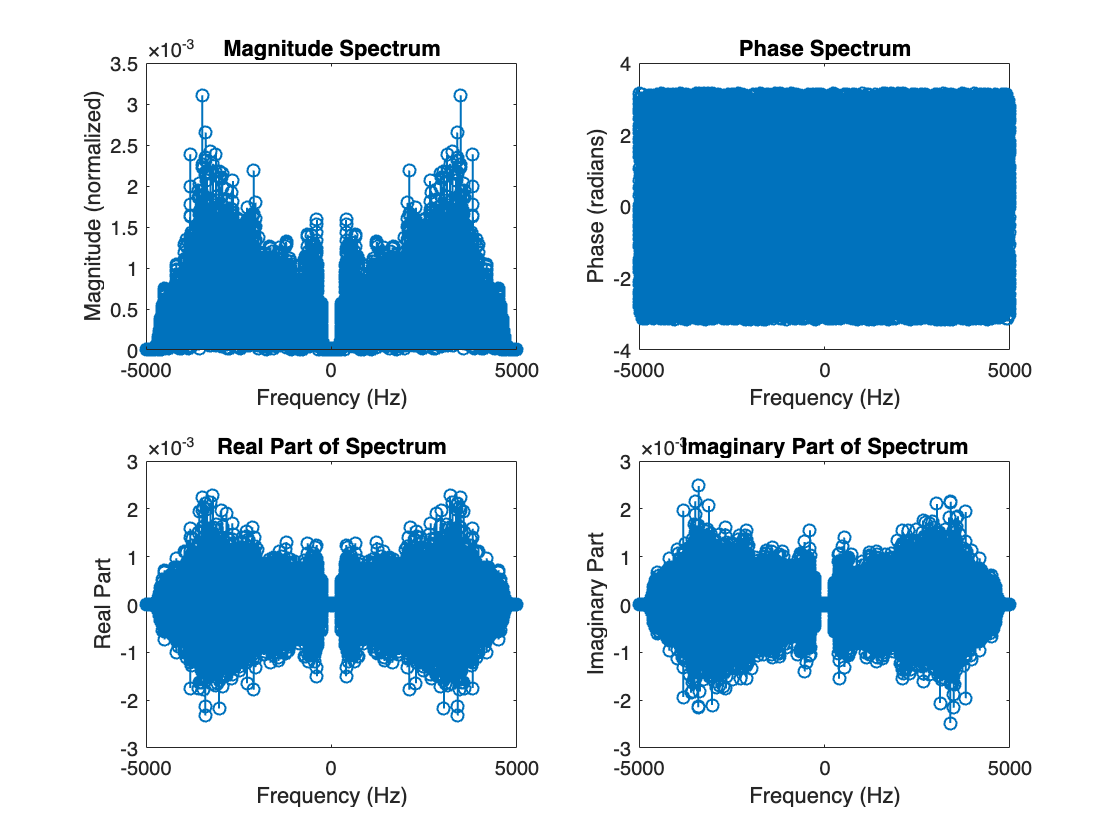

Original_magnitude = abs(Original_Y);

% Compute the magnitude spectrum of the filtered signal
[Filtered_Y, ~] = make_spectrum(filtered_data_signal, fs, spectral_resolution);

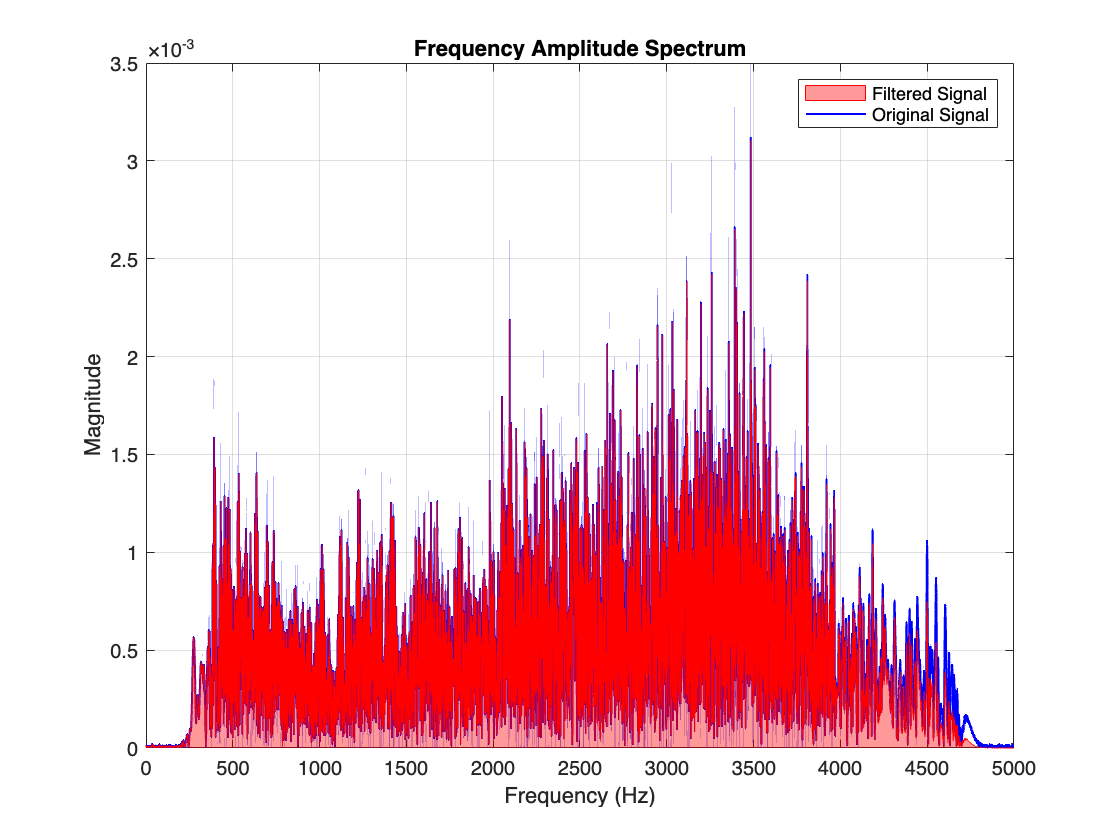

Filtered_magnitude = abs(Filtered_Y);

% Plot the magnitude spectra of both signals on the same plot
figure;

% Plot the original signal spectrum using 'plot'
plot(freq, Original_magnitude, 'b', 'LineWidth', 1); % Original signal in blue
hold on;

% Plot the filtered signal spectrum using 'area' with transparency
% Create a filled area under the filtered signal's magnitude spectrum
h_area = area(freq, Filtered_magnitude);
set(h_area, 'FaceColor', 'r', 'EdgeColor', 'r', 'FaceAlpha', 0.4);

% Set plot properties
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Amplitude Spectrum');
legend('Original Signal', 'Filtered Signal');
grid on;
xlim([0 fs/2]); % Limit x-axis to positive frequencies up to Nyquist frequency

hold off;